# Pb1

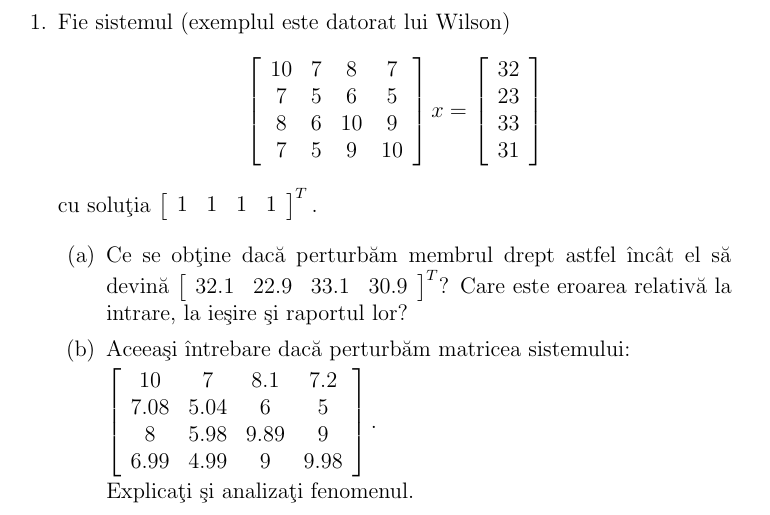

A = [10 7 8 7;
     7 5 6 5;
     8 6 10 9;
     7 5 9 10];

b = [32; 23; 33; 31];
% Membrul drept perturbat
b_pert = [32.1; 22.9; 33.1; 30.9];

% Solutia
x = [1; 1; 1; 1];

% Calculam inversa lui A
A_inv = inv(A); 

% Calculam solutia perturbata 
x_pert_inv = A_inv * b_pert;
x_pert = A \ b_pert;

% Calculam erorile relative - norma euclidiana
delta_b = b_pert - b;
eroare_b = sqrt(sum(delta_b.^2)) / sqrt(sum(b.^2));

delta_x_inv = x_pert_inv - x;
eroare_x_inv = sqrt(sum(delta_x_inv.^2)) / sqrt(sum(x.^2));  

raport_inv   = eroare_x_inv / eroare_b;

delta_x = x_pert - x;
eroare_x = sqrt(sum(delta_x.^2)) / sqrt(sum(x.^2)); 

raport   = eroare_x / eroare_b;


% Afisare rezultate
fprintf("Solutia perturbata CU INV(A):\n");

Solutia perturbata CU INV(A):


disp(x_pert_inv);

    9.2000
  -12.6000
    4.5000
   -1.1000



fprintf("Eroare relativa la b: %.6f\n", eroare_b);

Eroare relativa la b: 0.003332


fprintf("Eroare relativa la x: %.6f\n", eroare_x_inv);

Eroare relativa la x: 8.198475


fprintf("Raportul erorilor: %.2f\n", raport_inv);

Raportul erorilor: 2460.57



% Afisare rezultate
fprintf("Solutia perturbata FARA INV :\n");

Solutia perturbata FARA INV :


disp(x_pert);

    9.2000
  -12.6000
    4.5000
   -1.1000



fprintf("Eroare relativa la b: %.6f\n", eroare_b);

Eroare relativa la b: 0.003332


fprintf("Eroare relativa la x: %.6f\n", eroare_x);

Eroare relativa la x: 8.198475


fprintf("Raportul erorilor: %.2f\n", raport);

Raportul erorilor: 2460.57


% Membrul drept perturbat
A_pert = [10 7 8.1 7.2;
          7.08 5.04 6 5;
          8 5.98 9.89 9;
          6.99 4.99 9 9.98];
b = [32; 23; 33; 31];

% Solutia
x = [1; 1; 1; 1];


% Calculam inversa lui A
A_inv_pert = inv(A_pert);  

% Calculam solutia perturbata
x_pert_inv = A_inv_pert * b;
x_pert = A_pert \ b;

% Calculam erorile relative - norma euclidiana
delta_A = A_pert - A;
eroare_A = sqrt(sum(sum(delta_A.^2))) / sqrt(sum(sum(A.^2)));

delta_x_inv = x_pert_inv - x;
eroare_x_inv = sqrt(sum(delta_x_inv.^2)) / sqrt(sum(x.^2));
    
raport_inv   = eroare_x_inv / eroare_A;

delta_x = x_pert - x;
eroare_x = sqrt(sum(delta_x.^2)) / sqrt(sum(x.^2));
    
raport   = eroare_x / eroare_A;


% Afisare rezultatew
fprintf("Solutia perturbata CU INV(A_PERT):\n");

Solutia perturbata CU INV(A_PERT):


disp(x_pert_inv);

  -81.0000
  137.0000
  -34.0000
   22.0000



fprintf("Eroare relativa la A: %.6f\n", eroare_A);

Eroare relativa la A: 0.008730


fprintf("Eroare relativa la x: %.6f\n", eroare_x_inv);

Eroare relativa la x: 81.984755


fprintf("Raportul erorilor: %.2f\n", raport_inv);

Raportul erorilor: 9391.59






% Afisare rezultate
fprintf("Solutia perturbata FARA INV:\n");

Solutia perturbata FARA INV:


disp(x_pert);

  -81.0000
  137.0000
  -34.0000
   22.0000



fprintf("Eroare relativa la A: %.6f\n", eroare_A);

Eroare relativa la A: 0.008730


fprintf("Eroare relativa la x: %.6f\n", eroare_x);

Eroare relativa la x: 81.984755


fprintf("Raportul erorilor: %.2f\n", raport);

Raportul erorilor: 9391.59
